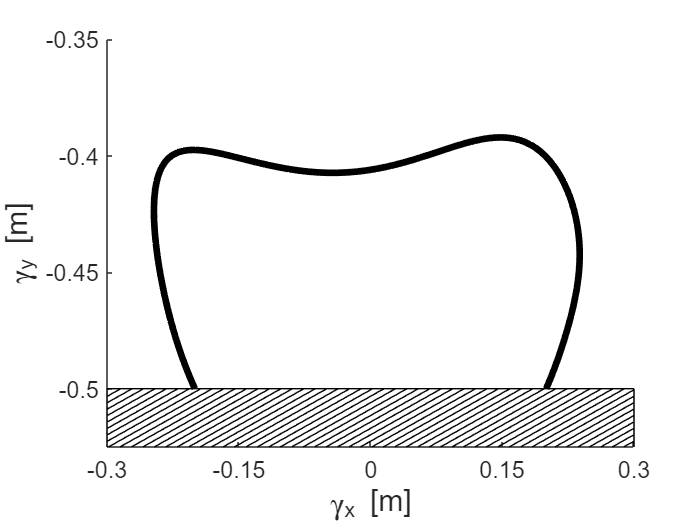

clear; close all; clc;
Beta_x = [-0.2,-0.259,-0.275,-0.384, 0.261,-0.017, 0.248, 0.267, 0.259, 0.2];
% Beta_y = [-0.5,-0.45,-0.406,-0.25,-0.35,-0.25,-0.545,-0.374,-0.45,-0.5];
Beta_y = [-0.5,-0.45,-0.406,-0.065,-1.031,0.095,-0.545,-0.374,-0.45,-0.5];
beta = [0, (1/3)*-4/(-0.531), 1-((1/3)*-4/-0.531), 1];
t = 0:0.01:1;
% t_mod = bezier(beta,t);
% x = bezier(Beta_x,t_mod);
x = bezier(Beta_x,t);
y = bezier(Beta_y,t);
figure;
hold on;
h = fill([-0.3, -0.3, 0.3, 0.3],[-0.6,-0.5,-0.5,-0.6],'k');
hp = findobj(h,'type','patch');
hatchfill(hp);
plot(x,y,'LineWidth',4,'Color','k');
set(gca,'FontSize',14)
xlabel("\gamma_{x} [m]","FontSize",18);
ylabel("\gamma_{y} [m]","FontSize",18);
set(gca,'XTick',[-0.3:0.15:0.3])
set(gca,'YTick',[-0.5:0.05:-0.35])

axis([-0.3,0.3,-0.525,-0.35]);



% figure;
% plot(t,t_mod);